%p_h1
%p_h2
%p_h3
%p_h4

%u_h1
%u_h2
%u_h3
%u_h4

% scalar in front (for quaternions)
q90 = sqrt(2)/2;
hoop1_pos = p_h1; %[3; 0; 2];
hoop1_quat = [q90, 0, q90, 0];
hoop2_pos = p_h4; %[0; 3; 2];
hoop2_quat = [q90, q90, 0, 0];
hoop3_pos = p_h3; %[-3; 0; 2];
hoop3_quat = [q90, 0, q90, 0];
hoop4_pos = p_h2; %[0; -3; 2];
hoop4_quat = [q90, q90, 0, 0];

box_distance = 0.5; % in meters
box_error = 0.025; % in meters

middle_point = [mean([hoop1_pos(1), hoop2_pos(1), hoop3_pos(1), hoop4_pos(1)]), mean([hoop1_pos(2), hoop2_pos(2), hoop3_pos(2), hoop4_pos(2)])];


% WAYPOINTS
[hoop1_entry, hoop1_exit] = hoop2ee(hoop1_pos, u_h1, box_distance);
[hoop2_entry, hoop2_exit] = hoop2ee(hoop2_pos, u_h4, box_distance);
[hoop3_entry, hoop3_exit] = hoop2ee(hoop3_pos, u_h3, box_distance);
[hoop4_entry, hoop4_exit] = hoop2ee(hoop4_pos, u_h2, box_distance);

%knots = [0 5 (7) 9 14 (16) 18 23 (25) 27 32 (34) 36 41];
knots = [0 5 9 14 18 23 27 32 36 41];
waypoints = cell(1,10);
waypoints{1} = [middle_point(1) ; middle_point(2) ; 0.5]; % start 
waypoints{2} = hoop1_entry;
waypoints{3} = hoop1_exit;
waypoints{4} = hoop2_entry;
waypoints{5} = hoop2_exit;
waypoints{6} = hoop3_entry;
waypoints{7} = hoop3_exit;
waypoints{8} = hoop4_entry;
waypoints{9} = hoop4_exit;
waypoints{10} = [middle_point(1) ; middle_point(2) ; 0.1];   %e nd


% CORRIDORS
hoop1_box = box(hoop1_pos, box_error);
hoop2_box = box(hoop2_pos, box_error);
hoop3_box = box(hoop3_pos, box_error);
hoop4_box = box(hoop4_pos, box_error);

box_mat = [hoop1_box, hoop2_box, hoop3_box, hoop4_box];


% Fix this...
order = 21;
corridors.times = [7 16 25 34];
corridors.x_lower = box_mat(1,:);
corridors.x_upper = box_mat(2,:);
corridors.y_lower = box_mat(3,:);
corridors.y_upper = box_mat(4,:);
corridors.z_lower = box_mat(5,:);
corridors.z_upper = box_mat(6,:);
% ...until here
make_plots = true;

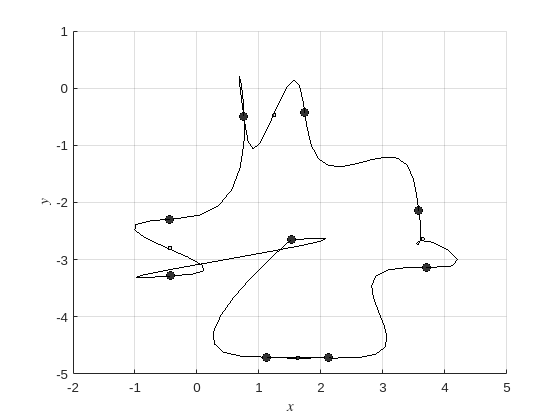

Optimization will be performed on end derivatives. This will improve optimization performance.
solving 1 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 2 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 3 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
Done!
Elapsed time is 0.135829 seconds.


clf
poly_traj = uas_minimum_snap(knots, order, waypoints, corridors, make_plots, u_h1, u_h2, u_h3, u_h4);

function [hoop_entry, hoop_exit] = hoop2ee(hoop_pos, hoop_unit_vec, box_d)
    %hoop_rotm = quat2rotm(hoop_quat);
    hoop_entry = hoop_pos - hoop_unit_vec * box_d;
    hoop_exit = hoop_pos + hoop_unit_vec * box_d;
end

function box_arr = box(center, error)

    x_lower = center(1) - error;
    x_upper = center(1) + error;
    y_lower = center(2) - error;
    y_upper = center(2) + error;
    z_lower = center(3) - error;
    z_upper = center(3) + error;

    box_arr = [x_lower; x_upper; y_lower; y_upper; z_lower; z_upper]; 
end